# Lab 3

Francesca Bennett

Collaborators: Taylor Prewitt, Natalie Shen

close all; clear all;


## Problem 1

First, a matrix of the given "bad" data is coded, and a seperate distribution of random data points that are "good" is made. The created data requires that, of 100,000 random data points, the standard deviation is no more than 0.4, with a mean of 12.

%bad data points
b=[10., 10.3, 2.1, 0., 0., 15.6, 22.3, 12.7];

%array of 100,000 random good data points
Dist1 = makedist('Normal','mu', 0,'sigma',0.4);
a=normrnd(12,.4,[1,100000]);



**Part 1.A.1: Plots**

First, a Histogram plot for the generated good data is shown, then a plot that shows the histogram with the bad data included. Finally, a full plot of all the data with the bad points that are outliers is shown.

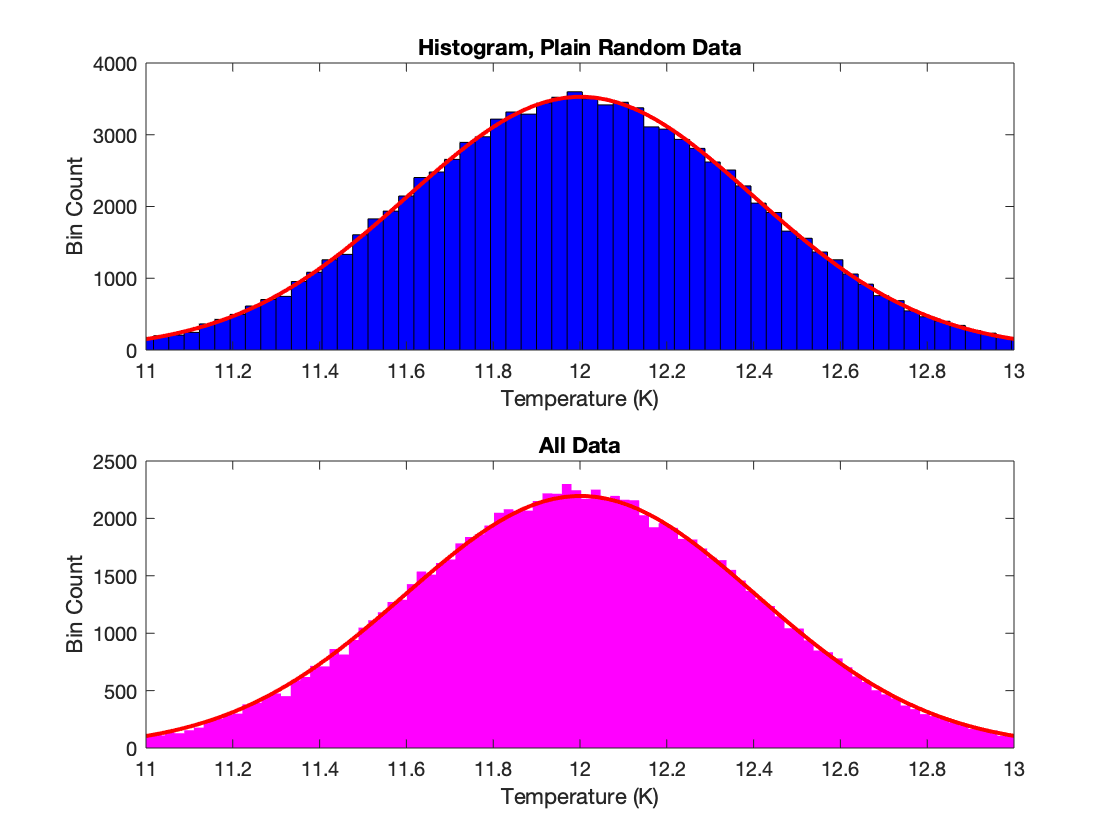


subplot(2,1,1);
hf1=histfit(a,100);
set(hf1(1),'FaceColor',"blue");
xlim([11,13]);
title("Histogram, Plain Random Data"); xlabel("Temperature (K)"); 
ylabel("Bin Count");

%old code below
%a = transpose((11.6 + (12.4-11.6).*rand(100000,1)));

%Good data with the bad data added, now matrix A:
A=[a b];

%Plot of Matrix A data
subplot(2,1,2);
hf2=histfit(A,1000);
set(hf2(1),'FaceColor',"magenta");
xlim([11,13]);
title("All Data"); xlabel("Temperature (K)"); 
ylabel("Bin Count");

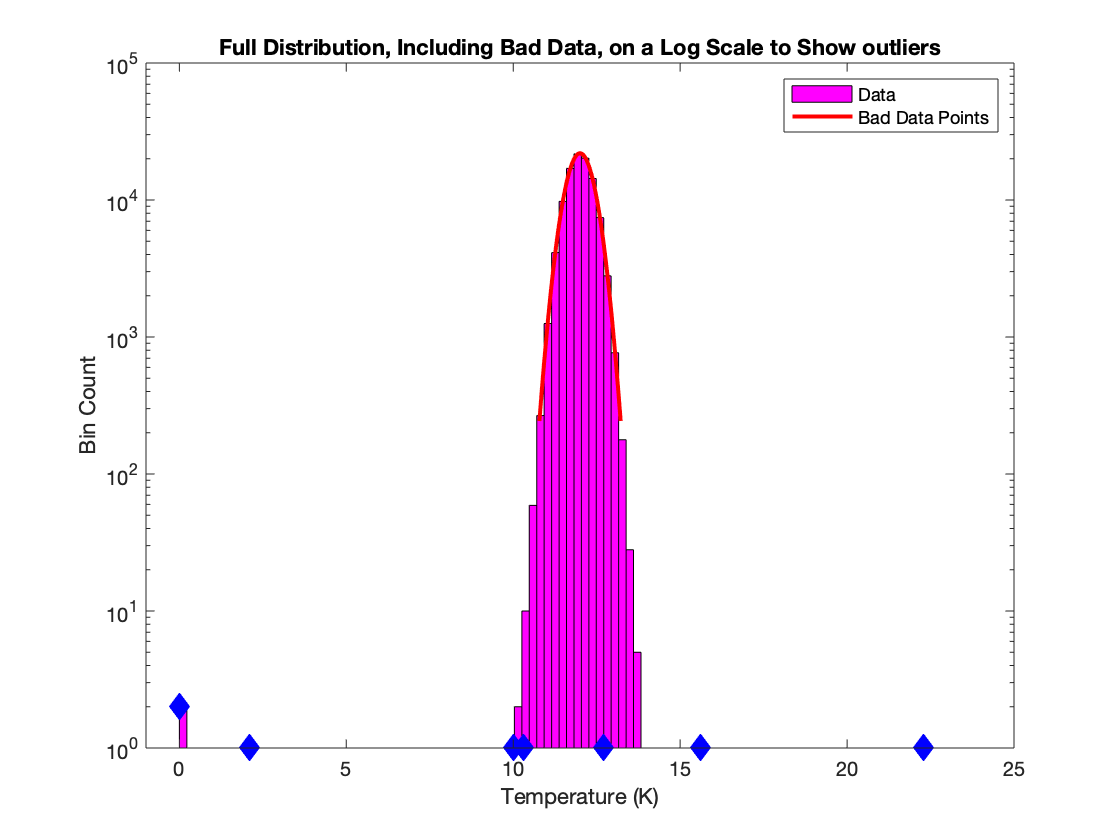


%Plot of all data, zoomed out, showing bad points
subplot(1,1,1);
hf3=histfit(A,100);
set(hf3(1),'FaceColor',"magenta");
xlim([-1,25]);
hold on
set(gca,'YScale','log');
title("Full Distribution, Including Bad Data, on a Log Scale to Show outliers");
xlabel("Temperature (K)"); ylabel("Bin Count");

%plotting bad data points to show location on graph
plot([10,10.3,2.1,0,15.6,22.3,12.7],[1 1 1 2 1 1 1],"Color","b","Marker","d", ...
    "MarkerFace","b","LineStyle","none","MarkerSize",10)
legend('show',"Data","Bad Data Points")
hold off




% title("With Bad Data")
% hold on
% plot([0,15.6,22.3],[2,1,1],'r*','LineWidth',2,'MarkerSize',15)


**Part 1.A.2: Statistical Question**

At what sigma outside of the mean is the most bad data removed and the most good data kept?

**Part 1.A.3: Representation of Question as Math**

The cumulative distribution function for a normal distribution is given as


$$F(x)=\frac{1}{\sigma\sqrt{2\pi}}\int^x_{-\infty}e^{-(x-\mu)^2/(2\sigma^2)}dx$$


which gives the probability that a value x falls between the upper bound of the integral and negative infinity.

We want to identify data points that fall outside of a given standard deviation, such as 2 sigma, for our mean of 12 Kelvin.

The Standard Normal Distribution can be used to simplify our process, using $z=\frac{(x-\mu)}{\sigma}$ and finding that $\Phi(z)=\frac{1}{\sqrt{2\pi}}\int^{z}_{-\infty}e^{-u^2/2}du$ and $\phi(z)=\frac{1}{2\pi}e^{-z^2/2}$.

We want to identify data that will be on the upper and lower ends of the distribution, however, because we are looking for anything that is very far from the mean. Therefore, we will need to account for both sides of the distribution by doubling any $\phi$ that used the lower or upper integral (an integral from $-\infty$ to x or from x to $+\infty$).

To find the percentage of all lost data, we calculate: $2\phi\times100$.

We need to identify how much good and bad data was been excluded via the filtering method.

To determine any lost good data (true-negative) in our filtering, we use: $2\phi\times100,000$, where a is the array for the good data.

To determine good data remaining (true-positive), we use: $2(1-\phi)\times[a]$.

To determine the bad data that is correctly excluded (false-negative), we use $b\geq x$, where b is the array for the bad data points.

To determine the bad data that is incorrectly kept (false-positive), we use $b<x$.

**Part 1.A.4: Truth Table**

Data is either an outlier, or not. One axis is the true label, and the other axis is if it is positive or negative. Every point has a true label: true or false.

True-positive: Kept good data

True-negative: Lost good data

False-negative: Lost bad data (which the intention)

False-positive: Kept bad data

In designing the truth table, it is helpful to examine the bad data point which falls closest to the correct mean: point 12.7. This bad data point is the hardest to remove and requires the most precision because it is the closest to the mean. 

%Probability of the value 12.7 falling outside of the mean of
%12 for a sigma of 0.4
B1=normcdf(12.7,12,0.4);

%Find all data lost, using phi=1-B1
Lost=[2*(1-B1)]*100;

%Find all good data lost
GoodLost=([2*(1-B1)]*length(a));

%All Good Data that was kept
GoodKept=length(a)-GoodLost;

%Sigmas associated with the probabiltiy B1
SigB1=norminv(B1);

%For a larger sigma

%For the bad data point 12.7, we have x=10.7
%we need to take the right side:
value=12-10.3;
right=12+value;

%The following steps are along the same lines as the above steps
B2=normcdf(right,12,0.4);

LossB2=[2*(1-B2)]*100;

SigB2=norminv(B2);

%LOST Good Data for sigma=SigB2=4.25, recorded in truth table
GoodLostB2=(([2*(1-B2)])*length(a));

%KEPT Good Data, sigma=4.25
GoodKeptB2=length(a)-GoodLostB2;

%5 sigma
%At 5 sigma, we should keep all correct data
ProbSig5=1/(3.5e6);

%location on distribution
Point=icdf("normal", 1-ProbSig5,12,0.4);

l=Point-12;
lower=12-l;
upper=12+l;
LossB3=2*ProbSig5*100;
%Lost bad data
GoodLostB3=((LossB3/100)*length(a));
%5 bad data values are eliminated 

%Kept good data
GoodKeptB3=length(a)-GoodLostB3;



**Part 1.B: Filter Catching Good Data**

*How does lost good data depend on the statistical threshold?*

A higher threshold, i.e. a lower sigma, results in more good data being lost because we are only accepting values that are closer to the center of the distribution. Essentially, we are being more picky, which results in losses we were not intending.

*Is this a predictable quantity?*

Yes, we can predict the quantity of good data lost, because we can count the values that fall outside of the chosen threshold and hence see how much was lost. We know that at lower thresholds such as sigma=5, we are not going to lose any data, because our distribution was made originally as a normal distribution, and 5 sigma is the range of a normal distribution. For real data, however, this won't be the case.

**Part 1.C: Is there Commission?**

*Is there any bad data that got in?*

At lower thresholds, i.e. using a higher sigma value to filter the data, there is bad data that remains in the distribution. This is because the "standards" have been relaxed, so to say, which allows us to keep all the good data.

*Was this avoidable?*

At higher thresholds, i.e. using a lower sigma value to determine what is filtered out, the bad data is entirely eliminated, but at the expense of some of the good data. We lose slightly less than 1% of the "good" data. 

*How does this depend on the threshold?*

A higher threshold (lower sigma, more picky) leads to less bad data being kept, but some good data loss, while at a lower threshold (high sigma, less picky), some bad data gets kept because our range for what is filtered as bad versus good is less strict.

However, this problem uses "good" data from a generated distribution, so it is easier to determine what exactly is "good" data, since the source of good data is essentially ideal. In actual experiments, it may be less clear what is "good" versus what is clearly incorrect data.

## Problem 2

**Part 1: Word Question**

To detect a potential asteroid, we must take into account the issue that movement that is not true movement is observed due to imaging error, which means we need a 5 sigma threshold to help eliminate the false inputs. 

We need to find a method that will filter out the image tracking errors that produce false data (movement where there is none), so that we can correctly calculate the distance an actual moving asteroid has moved.

How do we implement a 5 sigma threshold for detection of movement to determine the distance moved by a moving asteroid?

**Part 2: Mathematical Question**

Distance moved: $d=\sqrt{dx^2+dy^2}$

Consider:$D=\sqrt{\Delta x^2+\Delta y^2}$

Using a Rayleigh distribution, we have: $\sqrt{X_i^2+Y_i^2}$ where X and Y are normally distributed variables.

The Normal pdf is: $F(x)=\frac{1}{\sigma\sqrt{2\pi}}\int^x_{-\infty}e^{-(x-\mu)^2/(2\sigma^2)}dx$

The Rayleigh pdf is: $f(x,y\mid b)=\frac{x}{b^2}e^{-x^2/2b^2}$

We know that for 5 sigma, $f(5\sigma)=2.857\times10^{-7}$, where f is the normal pdf.

Using $r'=\sqrt{X_i^2+Y_i^2}$, we can say that $f(r')\leq f(5\sigma)$.

This allows us to define an r' that is more than the value of arcseconds.

## Problem 3				

**Part 1: Statistical Question**

For eight hours a night, over 15 days, we would expect (1 cosmic ray per minute)(7200 minutes)=7200 cosmic rays in a single patch of sky that is the size of the moon. During the nightly observation, the moon passes through this region of observation. Because we've only seen 6800 overall, it is expected that the moon's shadow does significantly impact our observation of cosmic rays. 

Is the moon blocking cosmic rays? $\to$Is there significant interference with the data due to the moon shadow?

If there is significant interference, our value of 6800 observed rays will have 5 sigma or greater distance from the mean of a normal distribution.

**Part 2: Mathemetical Translation of Question**

From the problem statement,


$$1 {\text{ GRB per min}}\times \frac{60\text{ min}}{1\text{ hour}}\times8{\text{ hours}}\times15\text{ days}=7200\text{ GRBs over 15 days}$$


This is the expected background for the moon-sized patch of sky being observed for cosmic rays.

We can use the Poisson distribution to evaluate the data, because we expect to see a particular count over each minute of obervation: the probability of seeing a cosmic ray in 1 minute is small and constant.

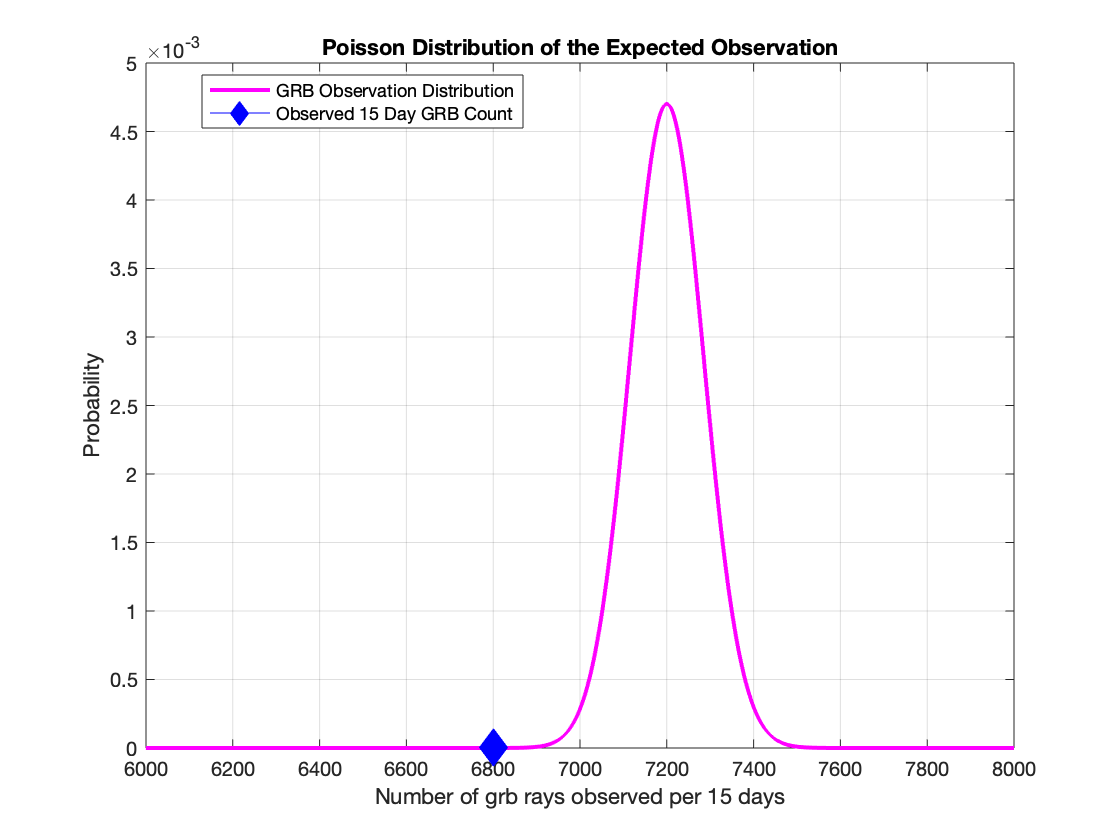

%Expected value, found above
EV=7200;

x=[0:8000];
P=poisspdf(x,EV);
stairs(x,P,'m',"LineWidth",2);
title('Poisson Distribution of the Expected Observation');ylabel("Probability");
xlabel("Number of grb rays observed per 15 days");xlim([6000 8000]);
grid on
hold on

%Including the observed value, 6800 grb rays
rays=6800;
plot(rays,0,"Color","b","Marker","d","MarkerSize",14,"MarkerFaceColor","b")
legend('show',"GRB Observation Distribution","Observed 15 Day GRB Count","Location","best")
hold off

**Part 3: Convert to Sigma**

To find the associated sigma value, we first take the intengral of the cumulative distribution function for a normal distribution:


$$F(x)=\frac{1}{\sigma\sqrt{2\pi}}\int^x_{-\infty}e^{-(t-\mu)^2/(2\sigma^2)}dt$$


This gives the probability. Using normcdf, we must use the observed GRBs, 6800, with the expected average of 7200, and the standard deviation of 7200.

We then take the inverse of the normal function to get our associated sigma.

%Finding the associated sigma value for 6800
sigma=sqrt(7200);

%probability for the observed counts
B2=normcdf(6800,7200,sigma);

%get sigma for the counts
S=abs(norminv(B2))

S = 4.7140

Our sigma for 6800 counts is: $\sigma =4.7140$

This is less than 5 sigma from the mean, but it is reasonably close. This gives us confidence that the moon's shadow does impact our observation, but we cannot be completely sure.

#### **Total Time Spent on Lab 3: 8 hours, at least**

Time breakdown: approx 2.5 hours on Tuesday (roughly 1pm to 4pm); at least 1 hour Saturday; at least 4.5 hours Sunday

**References:**

[https://www.mathworks.com/](https://www.mathworks.com/)

[https://en.wikipedia.org/wiki/Rayleigh_distribution](https://en.wikipedia.org/wiki/Rayleigh_distribution)

"Mathematical Methods in the Physical Sciences" 3rd ed, Mary L. Boas